# Double integrator system

MPC is applied for the regulation of a double integrator system, whose state equations in continuous time are


$$\dot x = Ax + Bu + E_x p + F_x d +G_x \\
y = Cx + Du + E_y p + F_y d + G_y$$


with

$A = \left[\begin{array}{@{}c@{}}
    0 & 1\\
    0 & 0
    \end{array} \right]$, $B = \left[\begin{array}{@{}c@{}}
    0\\
    1
    \end{array} \right]$, $C = \left[\begin{array}{@{}c@{}}
    1 & 0
    \end{array} \right]$, $D = 0$, $E_x = []$, $E_y = []$, $F_x = []$, $F_y = []$, $G_x = \left[\begin{array}{@{}c@{}}
    0\\
    0
    \end{array} \right]$, $G_y = 0$.

Define system matrices

A = [ 0, 1; 0, 0 ];
  
B = [ 0; 1 ];
    
C = [ 1, 0 ];

D = 0;

Create a continuous-time LTIsys object

nx = 2;    % Number of states
nu = 1;    % Number of inputs
ny = 1;    % Number of outputs
np = 0;    % Number of parameters
nd = 0;    % Number of unmeasurable inputs
nxref = 1; % Number of reference states

ctsys = ltiSys(nx, nu, ny, np, nd, 'ct');

Set system matrices

ctsys = ctsys.setMatrices('A', A);
ctsys = ctsys.setMatrices('B', B);
ctsys = ctsys.setMatrices('C', C);
ctsys = ctsys.setMatrices('D', D);

Set name of variables:

- the first element of the state is the position $s$

- the second element of the state is the velocity $v$

- the input is the acceleration $a$

- the output is the position $s$

ctsys = ctsys.setStateNames({'s', 'v'});
ctsys = ctsys.setInputNames({'a'});
ctsys = ctsys.setOutputNames({'s'});

The system is subject to the following constraints


$$\left[\begin{array}{@{}c@{}}
    -8\\
    -1
    \end{array} \right]
\leq x \leq
\left[\begin{array}{@{}c@{}}
    8\\
    1
    \end{array} \right]

 \\

-0.3 \leq u \leq 0.3$$


# MPC controller design

Select MPC type

mpcType = "explicit";

The system is discretized with sampling time $T_s = 1 s$, thus obtaining the following discrete time system


$$x_{k+1} = \hat A x_k + \hat B u_k\\
\hat y_k = C x_k + D u_k$$


Define the sampling time

Ts = 1;

The MPC controller is designed to track the first element of the state $s$, with $N = 5$, $N_u = 3$, $P = Q = \left[\begin{array}{@{}c@{}}
    1 & 0\\
    0 & 0
    \end{array} \right]$, $R = 10$.

N = 5;        % Prediction horizon
Nu = 3;       % Control horizon

P = [ 1, 0; 0, 0 ];  % MPC weight matrix
Q = [ 1, 0; 0, 0 ];  % MPC weight matrix
R = 10;              % MPC weight matrix

The following constraints are defined


$$\left[\begin{array}{@{}c@{}}
    -8\\
    -1
    \end{array} \right]
\leq x_{k+i} \leq
\left[\begin{array}{@{}c@{}}
    8\\
    1
    \end{array} \right],

\qquad i = 1, \dots, N_u

 \\

-0.3 \leq u_{k} \leq 0.3$$


xmin = [ -8, -1 ];
xmax = [ 8, 1 ];
umin = -0.3;
umax = 0.3;

% Create constraints object
constr = constraints(nx, nu, ny, np, nd, nxref, N);

% Set state constraints over the control horizon
constr = constr.setConstraints('x', xmin, xmax, 1:Nu-1);

% Set input constraints at current time instant
constr = constr.setConstraints('u', umin, umax, 0);

% Explicit MPC requires box contraints also on reference
rmin = xmin(1);
rmax = xmax(1);
constr = constr.setConstraints('r', rmin, rmax, 0);

Set controller options

options = struct( ...
             'P', P,          ... % matrix P of the cost function
             'Q', Q,          ... % matrix Q of the cost function
             'R', R,          ... % matrix R of the cost function
             'N', N,          ... % prediction horizon
            'Nu', Nu,         ... % control horizon
             'K', [],         ... % u = Kx+O, after the control horizon
             'O', [],         ... % u = Kx+O, after the control horizon
      'tracking', true,       ... % regulation or tracking problem
 'trackvariable', 1,          ... % name or index of the variable to track (only for tracking)
          'xref', [],         ... % constant reference state (only for regulation)
          'uref', []          ... % constant reference input (only for regulation)
    );

Design controller

switch mpcType
    
    case "explicit"
        ctrl = explicitMPCctrl(ctsys, Ts, constr, options);
        
    case "approximate"
        ctrl = explicitMPCctrl(ctsys, Ts, constr, options);
        approxOpts.nsamples = 4;
        approxOpts.np = [8 9 8];
        ctrl = ApproxMPCctrl(ctrl,approxOpts);
    
    otherwise % implicit
        ctrl = implicitMPCctrl(ctsys, Ts, constr, options);
end

 
Discretizing system...
 
Designing explicit MPC controller through MPT3...
mpt_plcp: 17 regions
 
Creating explicitMPCctrl object...
 
Done.
 


In case of explicit MPC or approximate MPC with$n_x + n_p + n_d + n_{xref} \leq 2$, plot the control function and the polytopic partition

% if mpcType ~= "implicit"
%     % Plot control function
%     ctrl.plot;
%     
%     % Plot polytopic partition
%     ctrl.plotPartition;
% end

Associate controller to LTI system

ctSysReg = ctsys.setController(ctrl);

The controller has been associated to the system.
Check the names below to ensure correct correspondence:
s <---> s
v <---> v
a <---> a
 


# Closed-loop simulation with MPC controller

Define an initial condition $x_0 = \left[\begin{array}{@{}c@{}}
    0\\
    0
    \end{array} \right]$

x0 = [ 0; 0 ];

Define $s_{ref} = 5$ as reference position

sref = 5;

Set $30 s$ as simulation time

T = 30;

Set constraints for simulation

opts.constraints = constr;

Closed-loop simulation (continuous time)

Simulating...
 
Done.
 


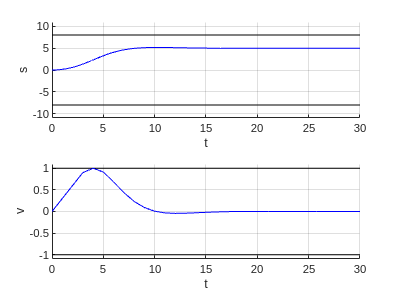

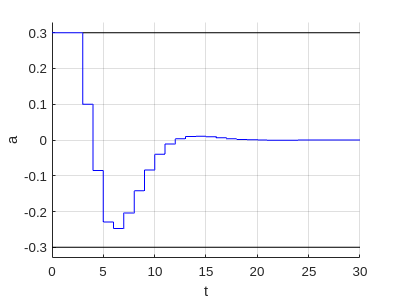

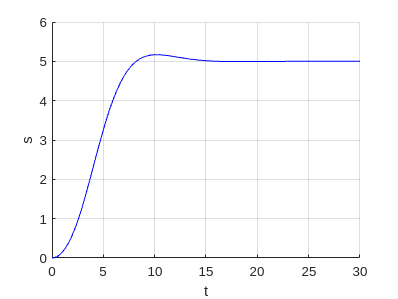

ctSysReg.simplot(T, x0, sref, opts);

# Observer design

Select the observer type

obsType = "predictor";

Set the observer sampling time to $T_{obs} = 0.5 s$

Tobs = 0.5;

Set noise covariance matrices as $Q = \left[\begin{array}{@{}c@{}}
    0.1 & 0\\
    0 & 0.1
    \end{array} \right]$ and $R = 0.1$

Q = 0.1*eye(nx);
R = 0.1*eye(ny);

Design observer

switch obsType
    
    case "predictor"
        obs = kalmanPredictor(ctsys, Tobs, Q, R);
    
    otherwise % filter
        obs = kalmanFilter(ctsys, Tobs, Q, R);
end

 
Discretizing system...
 
Designing Kalman predictor...
 
Done.
 


Associate observer to LTI system

ctSysObs = ctSysReg.setObserver(obs);

The observer has been associated to the system.
Check the names below to ensure correct correspondence:
s <---> s
v <---> v
a <---> a
 


# Closed-loop simulation with MPC controller and observer

Set initial observer state (optional)

opts.xest0 = x0;

Closed-loop simulation

Simulating...
 
Done.
 


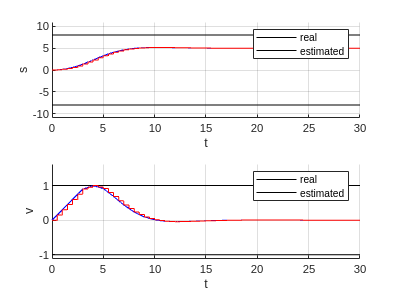

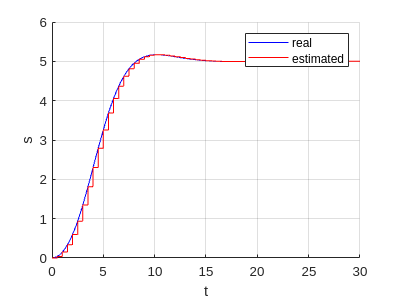

ctSysObs.simplot(T, x0, sref, opts);

# C and VHDL code generation

The toolbox allows for:

- generating circuit implementation of controller or observer or controller+observer on microcontroller (C code)

- generating circuit implementation of controller or observer or controller+observer on FPGA (VHDL code)

- generating Simulink model for closed-loop simulation of controller or controller+observer

- generating Simulink model for hardware-in-the-loop simulation of controller or controller+observer (the system runs on MATLAB, the controller/observer in an FPGA)

Set the signals range for circuit implementation

range.xmin = xmin;
range.xmax = xmax;
range.umin = umin;
range.umax = umax;
range.pmin = [];
range.pmax = [];
range.dmin = [];
range.dmax = [];
range.xrefmin = xmin(1);
range.xrefmax = xmax(1);
range.ymin = xmin(1);
range.ymax = xmax(1);

Set options for a microcontroller implementation. If the MPC controller is implicit, the parameters of Alternating Direction Method of Multipliers (ADMM) algorithm must be set.

if mpcType == "implicit"
    
    ADMMparameters.regPar = 32;   % Regularization parameter
    ADMMparameters.maxIter = 30; % Number of iterations
    
    cOptions = struct( ...
               'range', range,                  ... % signals range
               'ADMMparameters', ADMMparameters ... % parameters for ADMM algorithm
        );

else
    
    cOptions = struct( ...
               'range', range ... % signals range
        );
    
end

Set options for an FPGA implementation. If the MPC controller is implicit, some additional options have to be set:

- the integer part of the fixed point representation

- the FPGA device

- the parameters of ADMM

if mpcType == "implicit"
    
    vhdlOptions = struct( ...
               'architecture', 'fast',            ... % hardware architecture (can be 'fast' or 'small')
               'inputResolution', 12,             ... % resolution of the inputs
               'inputRepresentation', 'unsigned', ... % representation of the inputs
               'coeffResolution', 18,             ... % resolution of the coefficients
               'coeffIntResolution', 6,           ... % integer part of the coefficients (only for implicit MPC)
               'outputResolution', 12,            ... % resolution of the outputs
               'outputRepresentation', 'unsigned',... % representation of the outputs
               'frequency', 1e5,                  ... % FPGA working frequency
               'range', range,                    ... % signals range
               'fpgaBoard', 'xc7z020clg484-1',    ... % target FPGA (only for implicit MPC)
               'ADMMparameters', ADMMparameters   ... % parameters for ADMM algorithm (only for implicit MPC)
        );

else
    
    vhdlOptions = struct( ...
               'architecture', 'fast',            ... % hardware architecture (can be 'fast' or 'small')
               'inputResolution', 12,             ... % resolution of the inputs
               'inputRepresentation', 'unsigned', ... % representation of the inputs
               'coeffResolution', 12,             ... % resolution of the coefficients
               'outputResolution', 12,            ... % resolution of the outputs
               'outputRepresentation', 'unsigned',... % representation of the outputs
               'frequency', 1e5,                  ... % FPGA working frequency
               'range', range                     ... % signals range
        );
    
end

Create an embeddedSystem object (controller and observer)

es = embeddedSystem(ctSysObs, range);

Select whether to generate only controller or both controller and observer

obj = ctrl;

if isa(obj, "controller")
    sys = ctSysReg;
else % embeddedSystem
    sys = ctSysObs;
end

Generate controller/observer C files

obj.generateC(cOptions);

Binary search tree computed:
   number of nodes: 83
   minimum depth: 4
   mean depth: 6.119
   maximum depth: 10
   balance: 2.9367


Generate controller/observer VHDL files

obj.generateVHDL(vhdlOptions);

Destination folder for VHDL files: /home/ale/Code/MOBY-DIC/examples/C_circuit_1/FPGA_circuit_1/
Generating VHDL files...
Binary search tree computed:
   number of nodes: 83
   minimum depth: 4
   mean depth: 6.119
   maximum depth: 10
   balance: 2.9367
 
Relative error on matrix H:
0.069637%
Relative error on matrix K:
1.851e-15%
Relative error on matrix F:
0.30477%
Relative error on matrix G:
0.032121%
Relative quantization error on input points (for each dimension):
[0.02442     0.02442     0.02442] %
 
Destination folder for VHDL files: /home/ale/Code/MOBY-DIC/examples/C_circuit_1/FPGA_circuit_1/
Generating VHDL files...
Generated file /home/ale/Code/MOBY-DIC/examples/C_circuit_1/FPGA_circuit_1/Memory.vhd
Generated file /home/ale/Code/MOBY-DIC/examples/C_circuit_1/FPGA_circuit_1/FSM.vhd
Generated file /home/ale/Code/MOBY-DIC/examples/C_circuit_1/FPGA_circuit_1/pwagFunctionPackage.vhd
Generated file /home/ale/Code/MOBY-DIC/examples/C_circuit_1/FPGA_circuit_1/controller_package.vhd
G

Generate Simulink model

Model succesfully created in:
/home/ale/Code/MOBY-DIC/examples/model_3/
 
The model will now be opened...
 


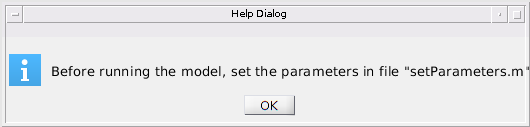

sys.generateSimulinkModel();

Generate Simulink model for hardware-in-the-loop simulation (to run this section you must close MATLAB and open "Model Composer and System Generator")

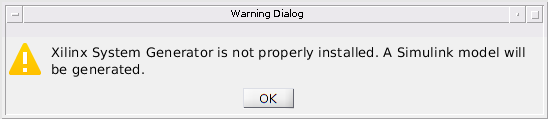

Model succesfully created in:
/home/ale/Code/MOBY-DIC/examples/model_1/model_1/model_1/
 
The model will now be opened...
 


% Toggle 'simVHDL' for hardware-in-the-loop simulation
simulinkOptions = struct( ...
                'simVHDL', 1 ...
    );

sys.generateSimulinkModel(simulinkOptions, vhdlOptions);